clc
clear

%frecuencias admitidas (8000, 11025, 22050 y 44100), el tipo
Fs = 44100;

recObj = audiorecorder(44100, 16, 1);

disp('Start speaking.')

Start speaking.


recordblocking(recObj, 3);
disp('End of Recording.');

End of Recording.


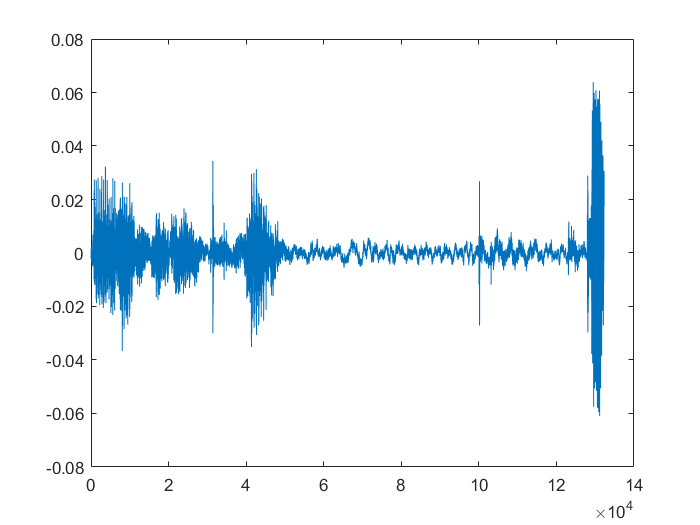


play(recObj);

y = getaudiodata(recObj);
plot(y);

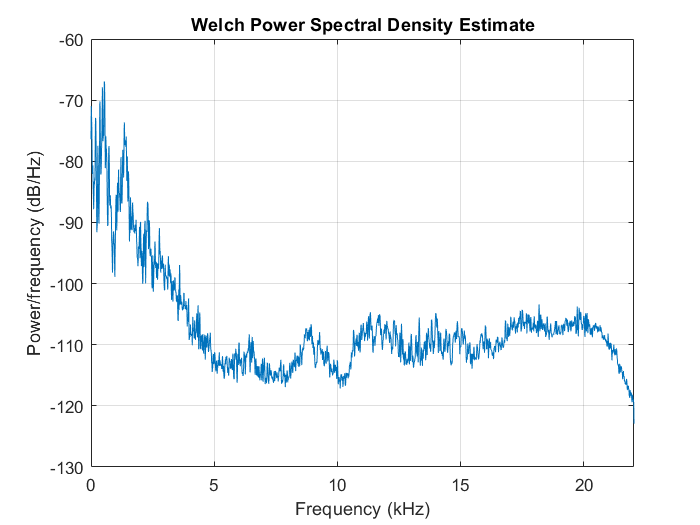

TL = 80e-3 ;
L = TL*Fs; 
NFFT = 2^nextpow2(L);
overlap= floor(0.7*L);
figure
pwelch(y,hamming(L),overlap, NFFT, Fs)

[pxx,f] =pwelch(y,hamming(L),overlap, NFFT, Fs);

[pks,locs] = findpeaks(10*log10(pxx),"NPeaks",2)

pks =   -70.9798
  -80.6976


locs =      2
     8


sort(f(locs))

ans =    10.7666
   75.3662


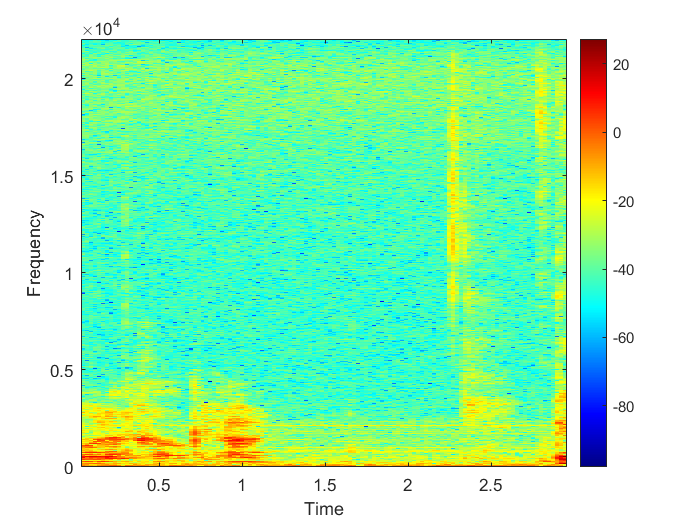


figure
specgram(y,NFFT,Fs,hamming(L),overlap); colorbar;



%Oli ya llegie
%hola